# 采用Farrow结构的分数时延滤波器

这个例子展示如何采用Farrow结构设计一个数字分数时延滤波器。数字分数延迟滤波器是一个非常有用的工具来调节信号的采样时间。举个例子，通常在数字调制解调器的同步中常见，其中延迟参数随着时间变化。这个例子说明farrow结构是一个非常常见的方法来实现FIR型延迟滤波器。

# 理想分数时延滤波器

理想的分数时延滤波器是一个线性相位全通滤波器。它的冲击响应是一个时移的离散sinc函数，并且是一个非因果滤波器。由于脉冲响应是无限长，因此它不能由有限的时间位移构造，因此它是不可实现的滤波器，必须近似处理。

# Farrow结构

为了计算分数时延滤波器的输出，我们需要根据已有的离散时间样本之间，估计输入信号的值。特殊的插值滤波器可以用于在任意点计算新的样本值。其中，基于多项式的滤波器是特别有趣的，因为一个特殊的结构 —— Farrow结构 ——允许简单的处理系数。特别是，Farrow结构的可调节性使其非常适合硬件实现。

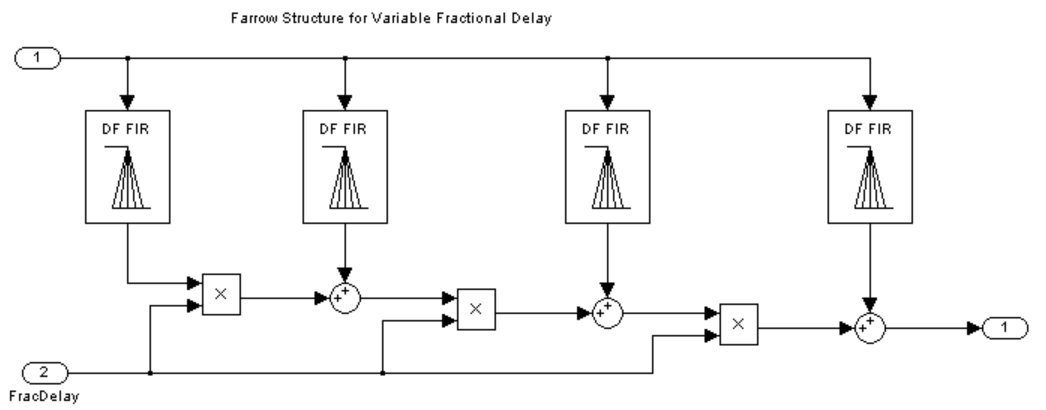

# 最大平坦准则逼近法(拉格朗日插值法)

拉格朗日插值法是一种时域方法，用于构造一种特殊情况下的多项式滤波器，输出信号近似为M次多项式。最简单的情况是(M=1)对应于线性插值。  让我们设计并分析一个线性分数延迟滤波器，它将单位延迟分成不同的分数：

clear;clc;

Nx = 1024;
Nf = 5;
yw = zeros(Nx,Nf);

%计算系统的传输函数
transferFuncEstimator = dsp.TransferFunctionEstimator(...
    'SpectralAverages',25,...                                           %谱估计的平均点数值
    'FrequencyRange','onesided');                                       %频率范围，单边带

%生成可视化——相位延迟模块
arrPlotPhaseDelay = dsp.ArrayPlot(...
    'PlotType','Line',...                                               %绘制类型——线型
    'YLimits',[0 1.5], ...                                              %Y轴尺度范围
    'YLabel','Phase delay',...                                          %Y轴描述——相位延迟
    'SampleIncrement',1/512);                                           %输入样本的数量

%生成可视化模块——幅度绘制模块
arrPlotMag = dsp.ArrayPlot(...
    'PlotType','Line',...                                               %绘制类型——线型
    'YLimits',[-10 1], ...                                              %Y轴尺度范围
    'YLabel','Magnitude (dB)',...                                       %Y轴描述——幅度
    'SampleIncrement',1/512);                                           %输入样本的数量

%生成分数时延滤波器
fracDelay = dsp.VariableFractionalDelay;

xw = randn(Nx,Nf);                                                      %生成随机信号
transferFuncEstimator(xw,yw);                                           %根据输入xw和输出yw计算传输函数

w = getFrequencyVector(transferFuncEstimator,2*pi);                     %获得频率轴
w = repmat(w,1,Nf);
tic,
while toc < 2                                                           %运行2s
    yw = fracDelay(xw,[0 0.2 0.4 0.6 0.8]);                             %分数时延滤波器，分别延迟 0 0.2 0.4 0.6 0.8 单位点
    H = transferFuncEstimator(xw,yw);                                   %计算传输函数
    arrPlotMag(20*log10(abs(H)))                                        %可视化幅度响应
    arrPlotPhaseDelay(-angle(H)./w)                                     %可视化相位响应
end
release(transferFuncEstimator)
release(arrPlotMag)
release(arrPlotPhaseDelay)
release(fracDelay)

对于任意的延迟数值，理想滤波器既有平坦的幅度响应以及平坦的相位延迟响应。近似的滤波器只有低频的部分符合要求。这意味着在实际的工程实现中，信号需要被过度采样，以保证线性分数延迟滤波器的正确工作(保证信号工作在低频部分)。在这里，我们应用2个不同延迟的分数延迟正弦波，并用示波器显示原始正弦波和2个延迟的正弦波。采样率1000Hz延迟0.2个点，即0.2ms延迟。

%生成示波器
scope = dsp.TimeScope('SampleRate',1000, ...                            %采样率1000Hz
                      'YLimits',[-1 1], ...                             %y轴缩放比例
                      'TimeSpan',.02, ...                               %时间尺度
                      'TimeSpanOverrunAction','Scroll');                %滚动模式
                  
sine = dsp.SineWave('Frequency',50,'SamplesPerFrame',Nx);               %生成信号发生器，50Hz
tic,
while toc < 2
    x  = sine();
    y = fracDelay(x,[.2 .8]);                                           %延迟输入信号0.2 0.8个点
    scope([x,y(:,1),y(:,2)])                                            %示波器可视化
end
release(scope);
release(fracDelay)

设计更高阶的拉格朗日插值，让我们比较一下三次拉格朗日插值和线性插值:

farrowFracDelay = dsp.VariableFractionalDelay( ...                      
    'InterpolationMethod','Farrow',...                                  %设计插值方法——Farrow
    'MaximumDelay',1025);                                               %最大延迟1025点

Nf = 2;                                                                 %生成2组信号
yw = zeros(Nx,Nf);                                                      %输出缓冲
xw = randn(Nx,Nf);                                                      %输入激励
H = transferFuncEstimator(xw,yw);                                       %估计传输函数
w = getFrequencyVector(transferFuncEstimator,2*pi);                     %获取频率轴
w = repmat(w,1,Nf);              
tic,
while toc < 2
    % Run for 2 seconds
    yw(:,1) = fracDelay(xw(:,1),0.4);                                   %对第一组信号延迟0.4ms /0.4个点
    yw(:,2) = farrowFracDelay(xw(:,2),1.4);                             %对第二组信号延迟1.4ms /1.4个点
    H = transferFuncEstimator(xw,yw);                                   %计算传输函数
    arrPlotMag(20*log10(abs(H)))                                        %绘制幅度响应
    arrPlotPhaseDelay(-unwrap(angle(H))./w)                             %绘制相位响应
end
release(transferFuncEstimator)
release(arrPlotMag)
release(arrPlotPhaseDelay)
release(fracDelay)

当使用拉格朗日近似时，增加的多项式阶数会略微增加有用的带宽，即微分滤波器的长度。脉冲响应的块数('系数'的行数特性)等于多项式的长度(‘系数的列特性)。采用其他的设计方法可以用来克服这一限制。注意到三阶滤波器的相位延迟是如何在直流时从0.4到1.4采样的。由于三次拉格朗日插值器是一个三阶滤波器，它可以实现的最小延迟为1.因此在本例中构造的延迟是1.4ms而不是0.4ms

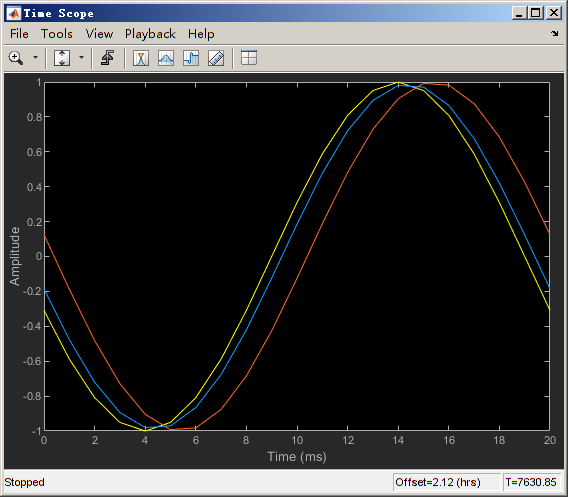

sine = dsp.SineWave('Frequency',50,'SamplesPerFrame',Nx);               %波形发生器
tic,
while toc < 2                                                           %仿真2秒
       x  = sine();                                                     %产生波形
       y1 = fracDelay(x,0.4);                                           %分数时延0.4ms
       y2 = farrowFracDelay(x,1.4);                                     %时延1.4ms
       scope([x,y1,y2])                                                 %可视化
end
release(scope);

release(fracDelay)

# **时变分数延迟**

Farrow结构的优势相比直接FIR的优点在于其可调性。在许多实际的应用中，时延是时变的，对于每个新的延迟，在直接FIR滤波器实现中，需要一组新的系数，但是在Farrow实现中，多项式的系数保持不变。

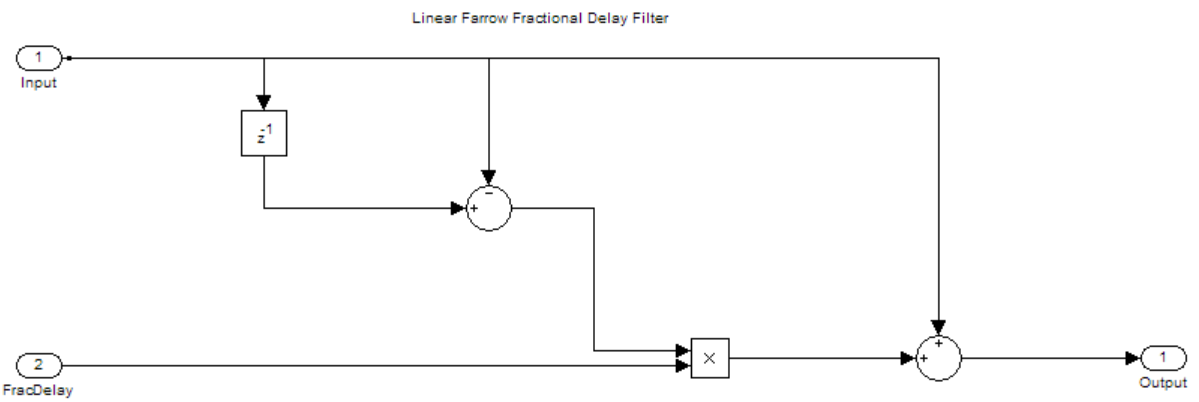

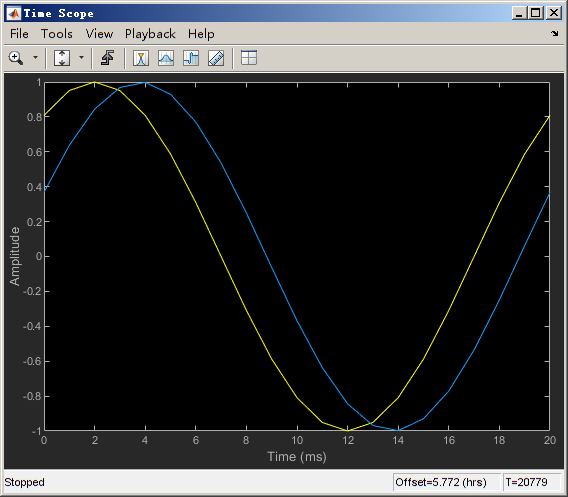

tic,
while toc < 5
    x  = sine();
    if toc < 1
        delay = 1;
    elseif toc < 2
        delay = 1.2;
    elseif toc < 3
        delay = 1.4;
    elseif toc < 4
        delay = 1.6;
    else
        delay = 1.8;
    end
    y = farrowFracDelay(x,delay);
    scope([x,y])
end
release(scope);

release(fracDelay)